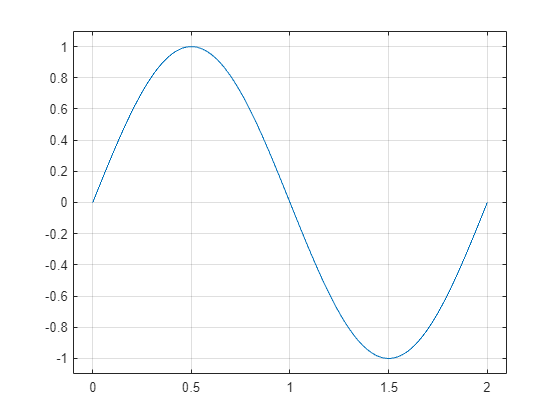

x=linspace(0,2,1000);
y=sin(pi*x);
plot(x,y);
xlim([-0.1,2.1]);
ylim([-1.1,1.1]);
grid on

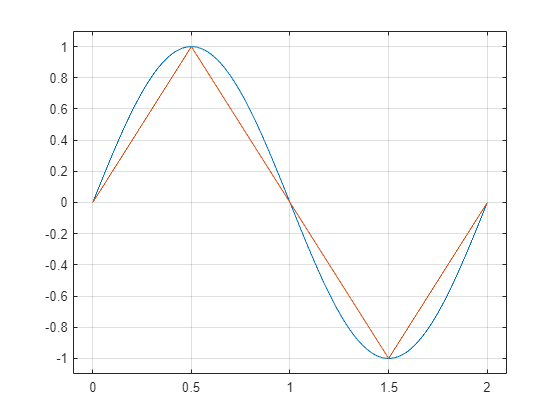

w1=2;w2=4;w3=1;w4=4;
b1=0;b2=-2;b3=-2;b4=-6;
w11=1;w12=-1;w13=-1;w14=1;
a1=ReLu(w1*x+b1);a2=ReLu(w2*x+b2);a3=ReLu(w3*x+b3);a4=ReLu(w4*x+b4);
salida=Lineal(w11*a1+w12*a2+w13*a3+w14*a4);
plot(x,y,x,salida);
xlim([-0.1,2.1]);
ylim([-1.1,1.1]);
grid on

function [a]= ReLu(z)
a=max(0,z);
end
function [a]= Lineal(z)
a=z;
end

